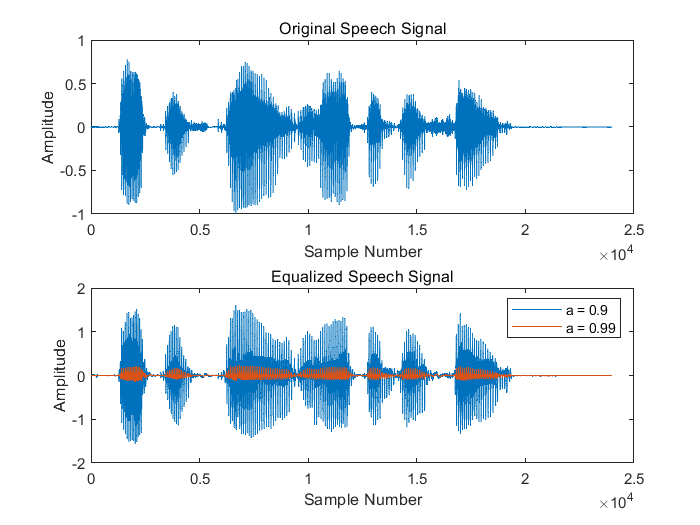

% Load speech file
[s, Fs] = audioread('s5.wav');

% Calculate standard deviation of speech signal
o = std(s);

% Apply IIR filter with a = 0.9
a = 0.9;
b = 1 - a;
y1 = filter(b, [1, -a], s);

% Apply IIR filter with a = 0.99
a = 0.99;
b = 1 - a;
y2 = filter(b, [1, -a], s);

% Plot original signal and filtered signals
figure;
subplot(2,1,1);
plot(s);
title('Original Speech Signal');
xlabel('Sample Number');
ylabel('Amplitude');
subplot(2,1,2);
plot(y1/o);
hold on;
plot(y2/o);
title('Equalized Speech Signal');
xlabel('Sample Number');
ylabel('Amplitude');
legend('a = 0.9', 'a = 0.99');

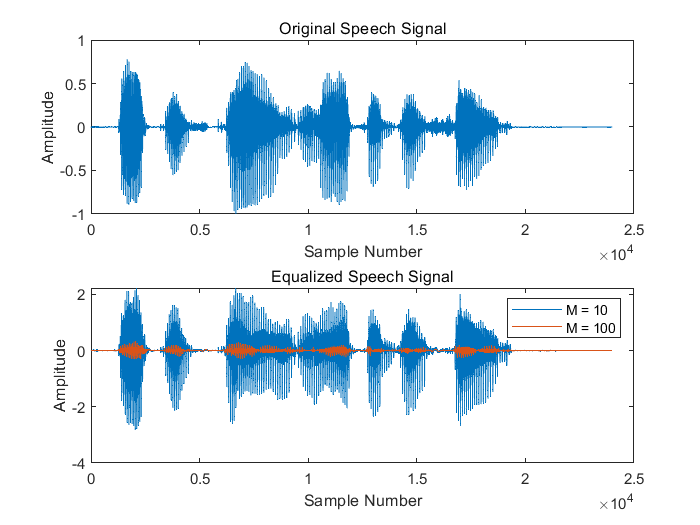


% Apply FIR filter with rectangular window of duration M = 10
M = 10;
h = ones(M,1)/M;
y3 = conv(s,h,'same');

% Apply FIR filter with rectangular window of duration M = 100
M = 100;
h = ones(M,1)/M;
y4 = conv(s,h,'same');

% Plot original signal and filtered signals
figure;
subplot(2,1,1);
plot(s);
title('Original Speech Signal');
xlabel('Sample Number');
ylabel('Amplitude');
subplot(2,1,2);
plot(y3/o);
hold on;
plot(y4/o);
title('Equalized Speech Signal');
xlabel('Sample Number');
ylabel('Amplitude');
legend('M = 10', 'M = 100');